# QGLAB Tutorial

Roy H. Goodman (NJIT), Gracie Conte (JHU-APL), and Jeremy Marzuola (UNC)

## Introduction

This tutorial gives a short introduction QGLAB, a MATLAB package for solving PDEs posed on quantum graphs. The software is available from this [GitHub repository](https://github.com/manroygood/Quantum-Graphs) and is described in more detail in this [preprint](https://arxiv.org/abs/2401.00561). Both the software repository and the preprint feature extensive instructions and examples, a few of which form the basis for this tutorial.

First, we should define what we mean by quantum graphs. The name is perhaps misleading. The phrase originally referred to metric graphs on which a Schrodinger operator has been defined, but has since come to refer to any problem on which a differential equation is solved on the *edges* of a graph, subject to compatibility conditions at the vertices. A **metric graph** is a graph $\Gamma$ consisting of a set $\mathcal{V}= \{ \mathtt{v}_1,\ldots,\mathtt{v}_n \}$of vertices and a set$\mathcal{E} = \{ \mathtt{e}_1,\ldots,\mathtt{e_m} \}$of directed edges. Several examples are plotted in the next section. Each edge $\mathtt{e}_j$ can be thought of a line segment of length $\ell_j$beginning at one vertex $\mathcal{v_{j_1}}$ and ending at a vertex $\mathcal{v_{j_2}}$. We may place a coordinate $0<x<\ell_j$ on this edge, and define a function $\psi_j(x)$ on it, and therefore along the whole metric graph $\Psi=(\psi_1,\ldots,\psi_m)$. To define a function space and differential operators, we must specify vertex conditions. The most common are Neumann-Kirchhoff conditions consisting of the *continuity condition*

$\Psi(\mathtt{v}_k) \equiv \psi_i(\mathtt{v}_k) = \psi_j (\mathtt{v}_k), \forall \mathtt{e}_i, \mathtt{e}_j \in \mathcal{V}_k$,

where $\mathcal{V}_k$ is the set of edges connected to vertex $\mathtt{v}_k$ and *zero flux condition*

$\sum_{\mathtt{e}_m \in \mathcal{V}_k} w_m \psi_m'(\mathtt{v}_k)  = 0$.

Here the derivative is taken assuming that $\mathtt{v}_k$ is the initial point of edge $\mathtt{e}_m$ so that $x$ is increasing. This latter condition may be replaced with a Dirichlet condition or a Robin-type condition.

Our preprint contains an extensive list of references discussing quantum graphs. For the field to grow, researchers must be able to efficiently and accurately set up and common types of problems on quantum graphs and visualize their solutions. We wrote QGLAB to meet this need. 

MATLAB provides a built-in directed graph class and a number of functions implementing common graph computations. QGLAB extends this capability to define a quantum graph object and overloads many MATLAB functions such as `eigs`, `plot` and `spy` to work seamlessly with these objects.

The most important mathematical object defined by QGLAB is a discretized Laplacian operator. We implement this using a design philosophy espoused by Aurentz and Trefethen (block operators) that handles differential equations at points on the interiors of the edges separately from the vertex conditions. Edge $\mathtt{e}_m$ is discretized at $N_m+2$ points, $N_m$ of which can be considered as interior points, with the last two considered boundary points. The fundamental idea is to construct a second derivative matrix of dimension $N_m \times (N_m+2)$. Thus $N_m$ equations are used to define the differential equation and $2$ are used to discretize the vertex conditions.

This requires us to three matrices: the discretized Laplacian $\mathbf{L}_{\mathrm{int}}$ and an interpolation matrix $\mathbf{P}_{\mathrm{int}}$ that represent equations defined at points on the edges' interiors a vertex condition matrix, and an interpolation matrix $\mathbf{M}_{\mathrm{VC}}$. We have implemented both second-order centered-difference discretization and a spectrally accurate Chebyshev collocation approximation. The block operators make it simple to work with either discretization and to switch between them.

We first describe the basics of using MATLAB's graph capabilities. Next we describe how to define a quantum graph using QGLAB. Finally we solve a few example problems:

### MATLAB graph basics

MATLAB has built-in data types for graphs and directed graphs. We have used the latter as the basic building block for a set of routines (listed in accompanying `Contents.m` file) for computing with linear and nonlinear quantum graphs: directed graphs which solve PDE's on the edges, subject to some kind of boundary condition or matching condition at the vertices.

We first show how to create and display a graph:

sources=[1 1 2 1 3];
targets=[1 2 2 3 2];
G = graph(sources,targets)

G =   graph with properties:

    Edges: [5×1 table]
    Nodes: [3×0 table]


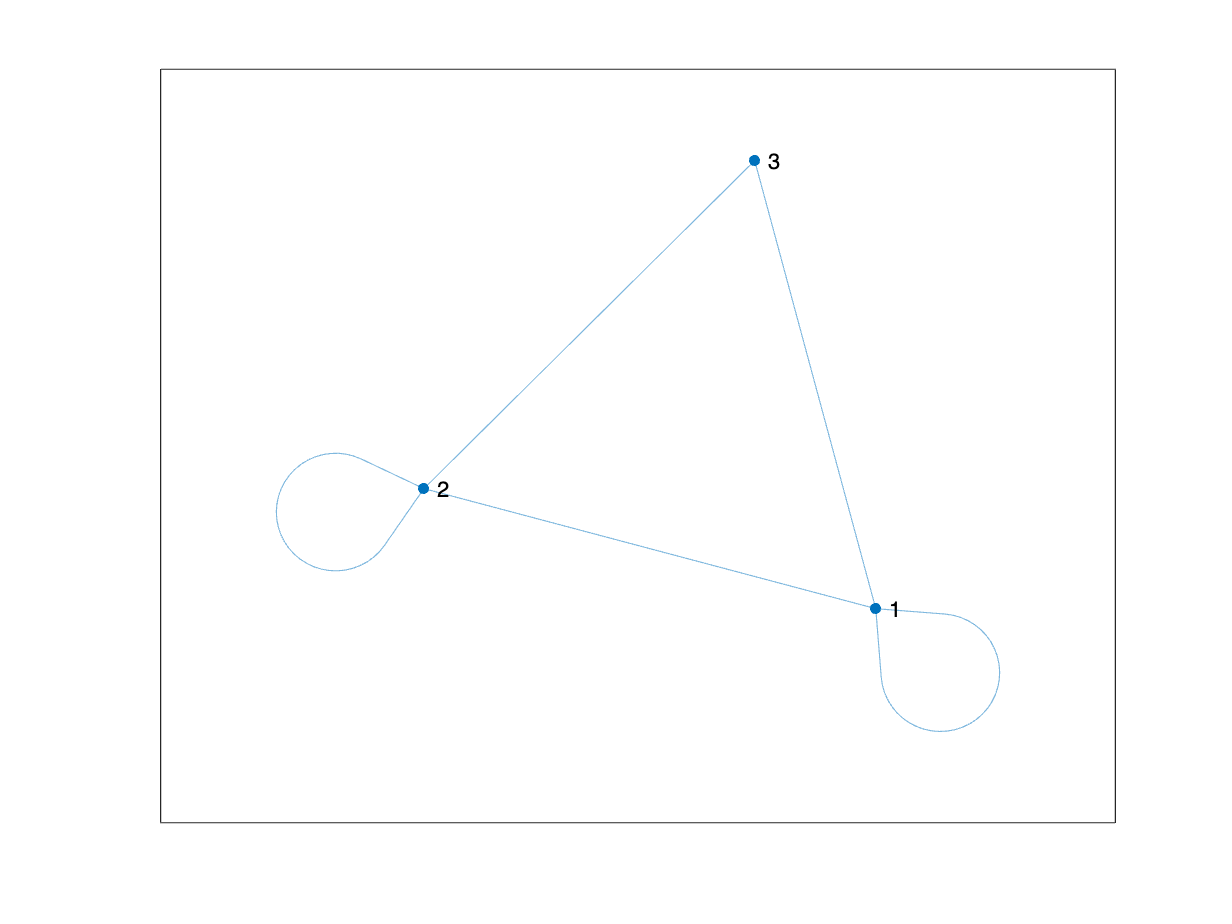

plot(G)

The input consists of two integer-valued vectors of equal length, from which the graph is built. Each element of each list give the beginning and ending vertex of the corresponding edge. MATLAB refers to these as the source and target nodes of the given edge. The digraph type differs from the graph type in that each edge is directed from the source to the target. It is digraphs that we use to build quantum graphs.

DG= digraph(sources,targets)

DG =   digraph with properties:

    Edges: [5×1 table]
    Nodes: [3×0 table]


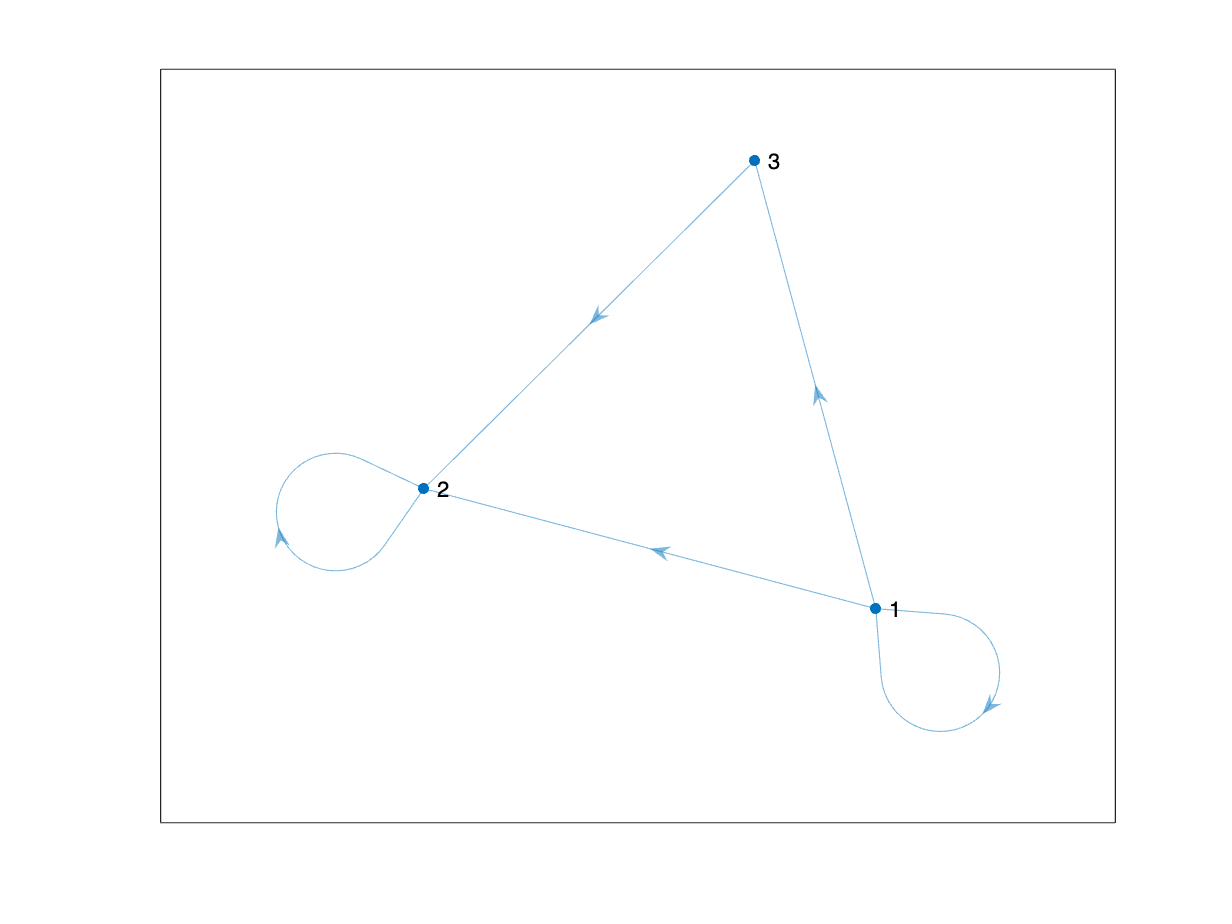

plot(DG)

Note that the two data structures appear the same, but MATLAB does treat them differently and has some distinct commands for dealing with the two of them. For example the function `degree` calculates the degree of a node in a graph, but does not work on digraph, which has separate functions `indegree` and `outdegree` that compute incoming and outgoing degrees. Let's look at the `Edges` component:

DG.Edges

ans = 5×1 table
    EndNodes
    ________

     1    1 
     1    2 
     1    3 
     2    2 
     3    2 


Both the `Edges` and `Nodes` components are defined as MATLAB `tables`. At this point the `Edges` component has one entry called `EndNodes`. The graph is a purely topological entity. The lengths of the displayed edges are arbitrary. The real usefulness of the data structure is that we can add additional data to both the edges and the nodes. For example we can associate the elements of a vector `L` to each edge, so long as `length(L) = length(EndNodes)`.

DG.Edges.L=[1;3;5;7;9];
DG.Edges

ans = 5×2 table
    EndNodes    L
    ________    _

     1    1     1
     1    2     3
     1    3     5
     2    2     7
     3    2     9


The Nodes table is initially empty

DG.Nodes


ans =

  3×0 empty table



but we can add data to each node in a similar manner.

DG.Nodes.mass = [1;4;9];
DG.Nodes

ans = 3×1 table
    mass
    ____

     1  
     4  
     9  


### Graphs MATLAB Can't Work With (version 2017b and earlier).

Before version 2018a, Matlab's `digraph `structure could not handle multiple edges sharing the same source and target. Therefore a graph such as the *mandarin graph*, which has two vertices, and three separate edges connecting them cannot be represented.

The following will return an error in MATLAB versions older than 2018a.

source=[1 1 1 2]; target=[1 2 2 2];
quantumGraph(source,target,1);

### Constructing the Quantum Graph

To create the quantum graph routines, we first created a quantum graph class, which is built on top of the digraph class, and added appropriate data for quantum graph problems:

source=[1 1 2];
target=[1 2 2];
L = [2*pi,4, 2*pi];
Phi = quantumGraph(source,target,L);

There can be other fields associated with the quantum graph but these are either optional fields, or fields set to the default, and must be set in a slightly different way. 

Most of the information is associated with the edges

`L:` (required)the vector of lengths (if scalar than repeated)

`nx:` (optional) the number of discretization points on each edge (if scalar then `nx` is the density of points per unit length and the same value is used on each edge)

`x` and `y`: (optional, created if nxVec is set) the independent and dependent variables on each edge. `y` is set to `NaN` on initialization. Only created if nxVec specified. If `length(nxVec)==1`, then it is interpreted as the density of discretizatio points per unit length

Phi.Edges

ans = 3×7 table
    EndNodes    Weight      L       nx           x                 y           integrationWeight
    ________    ______    ______    ___    ______________    ______________    _________________

     1    1       1       6.2832    126    {128×1 double}    {128×1 double}       {[0.0499]}    
     1    2       1            4     80    { 82×1 double}    { 82×1 double}       {[0.0500]}    
     2    2       1       6.2832    126    {128×1 double}    {128×1 double}       {[0.0499]}    


There are two variables associated to the nodes:

`y`: the dependent variable

`robinCoeff`: optional the constant determining the Robin boundary condition used in the Laplacian and in interpolating `y` from the edges to the nodes. This optional argument defaults to zero, i.e. to Kirchoff/Neuman boundary conditions. May be specified as scalar or vector. At leaf nodes only, Dirichlet boundary conditions can be used. This is specified by a `NaN`. Specifying `NaN` at a non-leaf node will return an error.

Phi.Nodes

ans = 2×2 table
    robinCoeff     y 
    __________    ___

        0         NaN
        0         NaN


The above quantum graph is suitable for running the secular determinant codes below. This symbolic calculation does not depend on a discretization. However if you want to do numerics, you will need to set up vectors of *x*- and *y*- values along each edge. This involves first defining a vector `nx` containing the number of x values along each edge (including the endpoints), and then calling the following two routines to set up fields to hold the independent and dependent coordinates. For now, only uniform discretizations are allowed  but in the future we will add support for Chebyshev discretizations. Note that if `nxvec` is specificed but `Discretization` is not, then `Discretization` defaults to `Uniform`. The general syntax is now

`dumbbell=quantumGraph(source,target,L,'Key1',value1, 'key2',value2,...)`

The three required input parameters must appear in that order, followed by the optional parameters, specified as key-value pairs, that can appear in any order. The optional arguments, for now, are

- `nxvec `(associated to edges)

- `robincoeff `(associated to nodes)

- `Discretization `(property of graph)

- `plotCoordinateFcn `(property of graph, allows overloading of `plot)`

In addition, there are methods to add or change these values.  

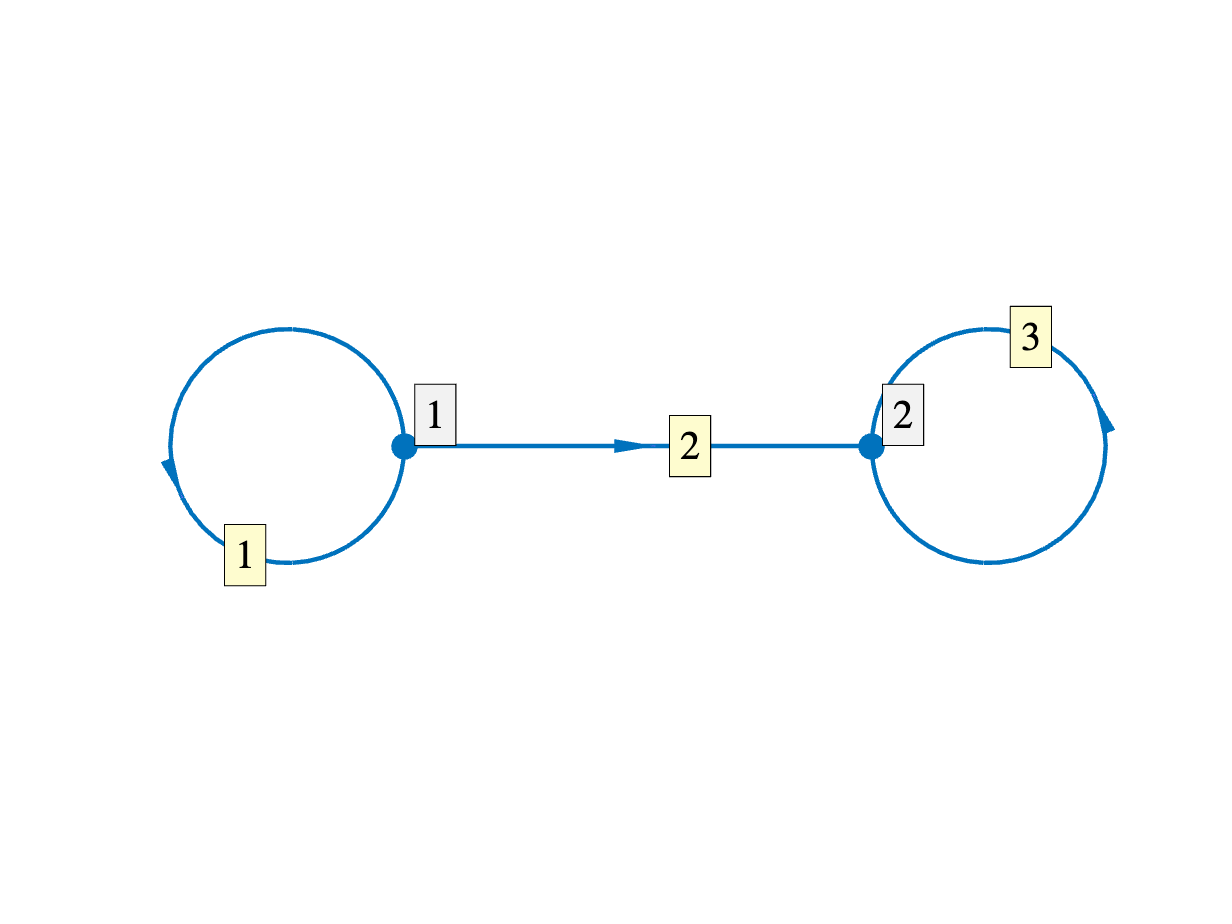

Phi=quantumGraph(source,target,L,...
    'Discretization','Chebyshev',...
    'nxvec',[63 20 63],...
    'plotCoordinateFcn',@dumbbellPlotCoords);
Phi.plot('layout')

The final name-value pair specifies the name of a user-defined function that sets up the coordinates and enables the plots of eigenfunctions given below. 

### Template functions

For many of our favorite graphs, we have created template functions, which are stored in the directory `source/templates`. All we need to do to create a dumbbell matrix is to enter

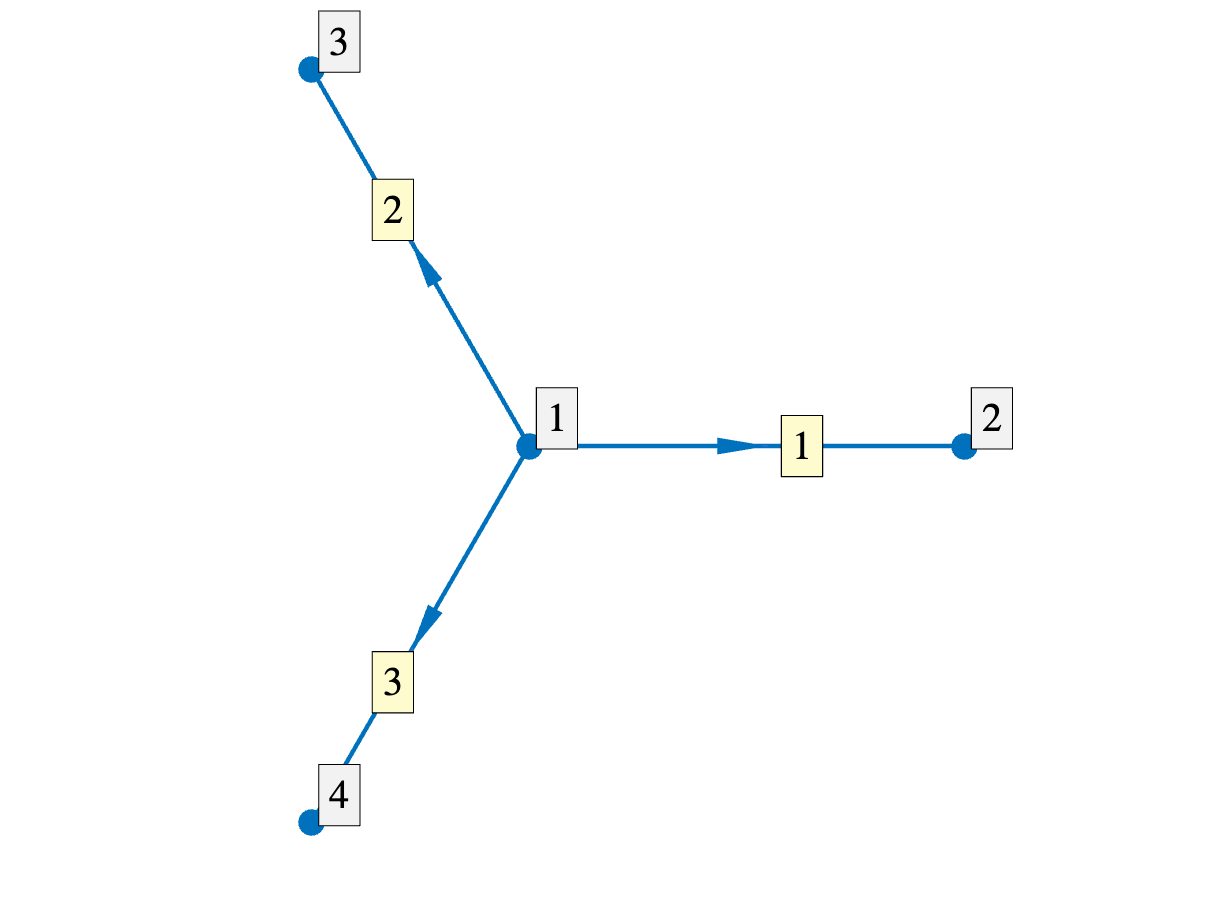

Phi = quantumGraphFromTemplate('star');
Phi.plot('layout')

The template file contains default values for constructing the quantum graph. By default a uniform grid is used with centered difference discretization.  Defaults can be overridden using key-value pairs. Each template constructor contains a program that defines the graph's layout for plotting.

### Visualizing the quantum graph discretization

As discussed in the introduction, QGLAB uses a block-matrix formulation to discretize differential equations whose space derivatives are given by Laplacians. This requires the construction of three matrices: the discretized Laplacian, an interpolation matrix, and a vertex condition matrix.  These matrices are constructed directly from the quantum graph object. If a discretization is specified, then they are defined when the quantum graph is initially constructed. 

#### Finite Difference

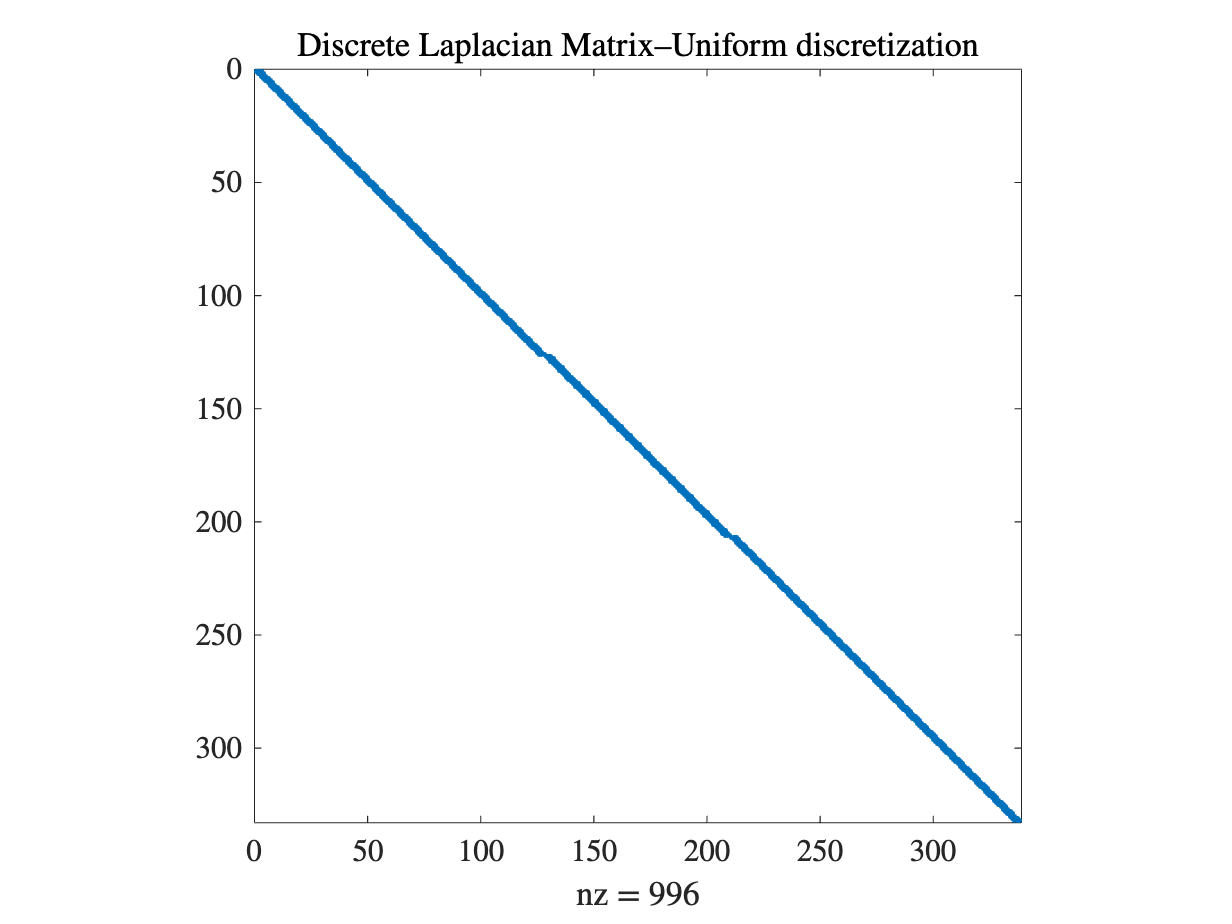

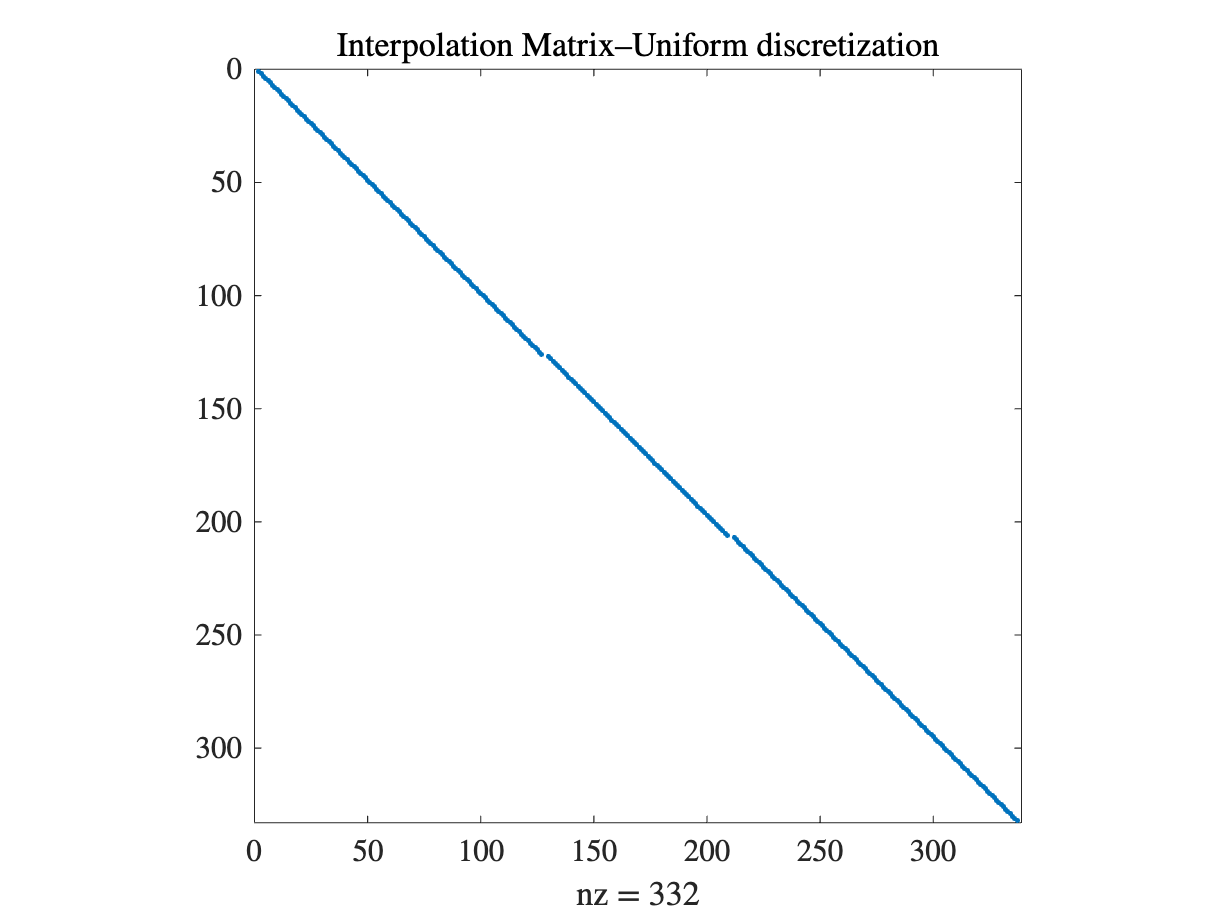

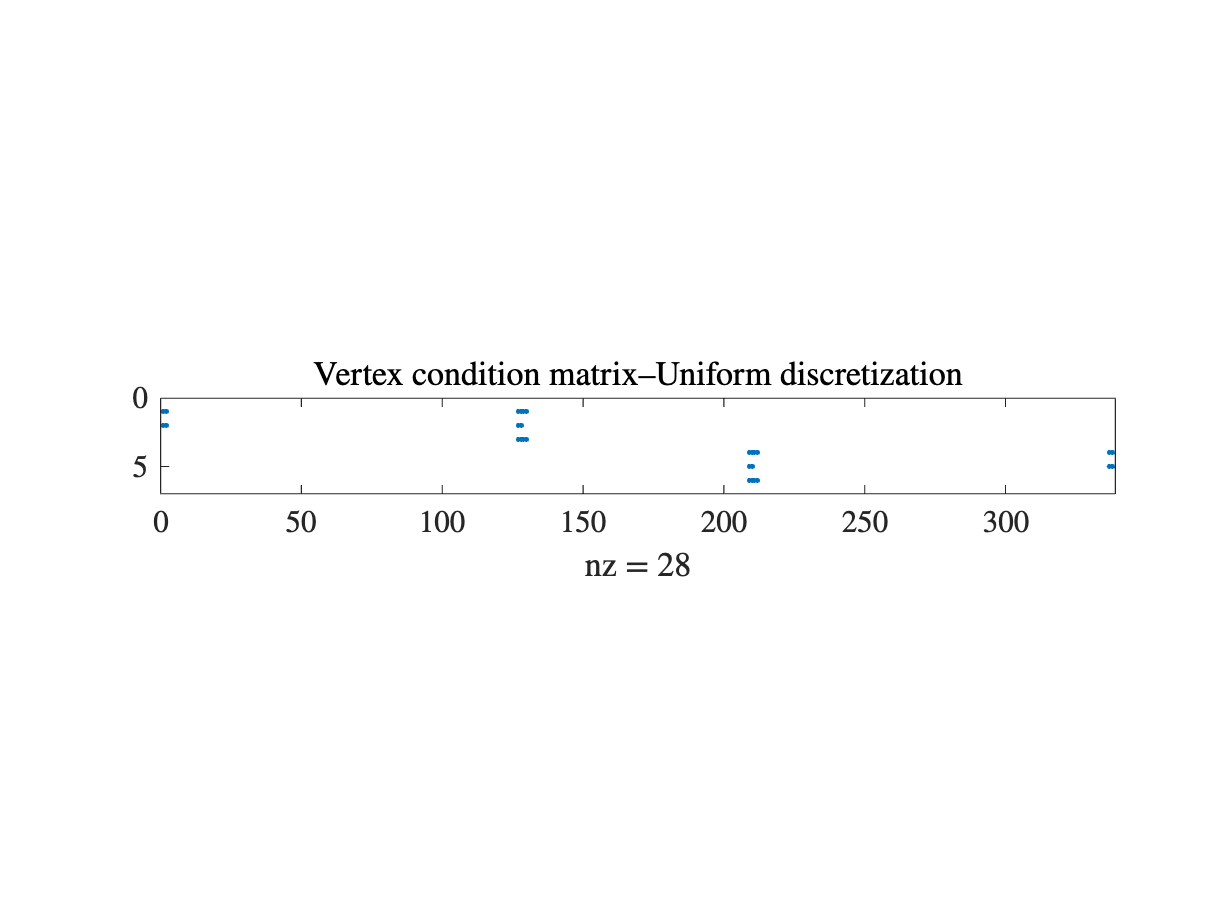

Phi = quantumGraphFromTemplate('dumbbell');
Phi.spy

#### Chebyshev

This, of course, gives higher accuracy at the expense of constructing blockwise-dense matrices.

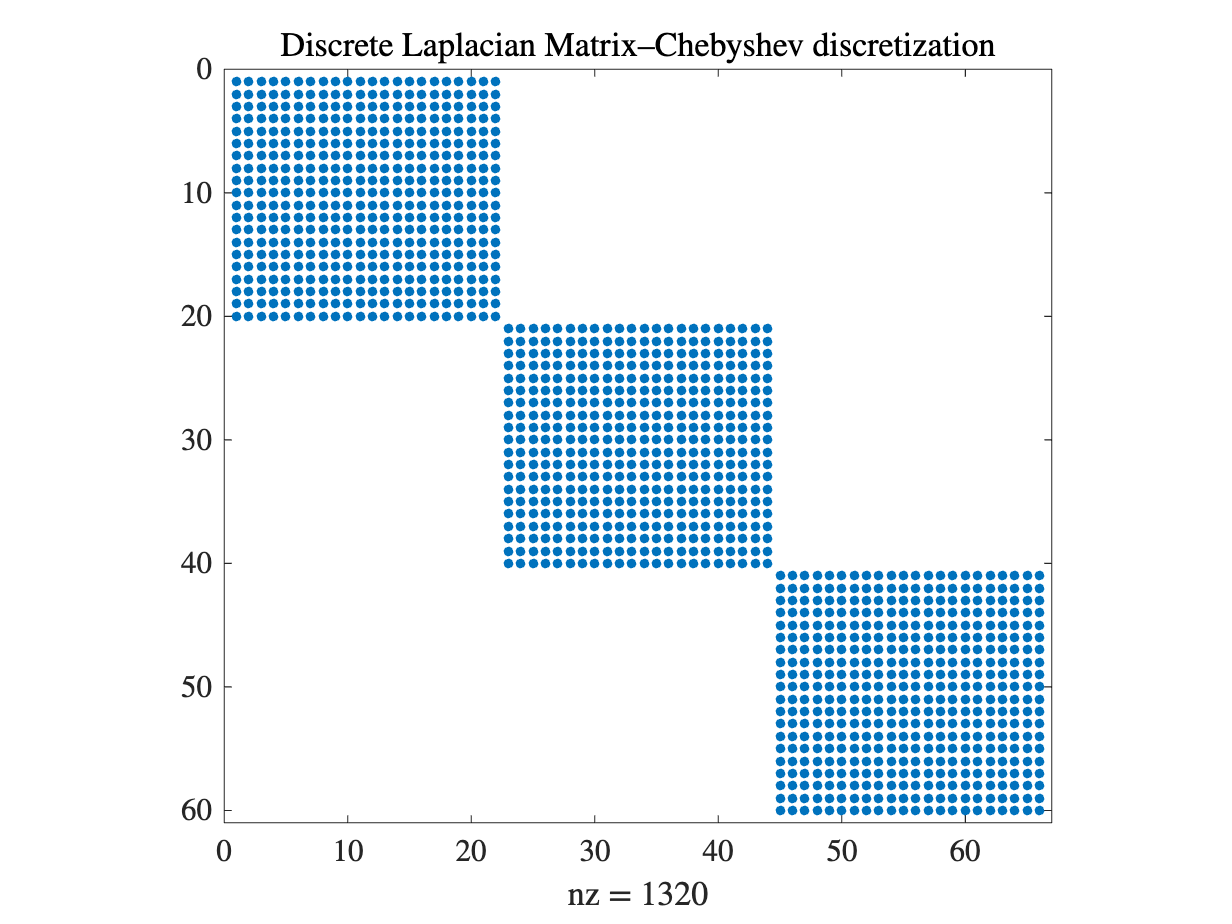

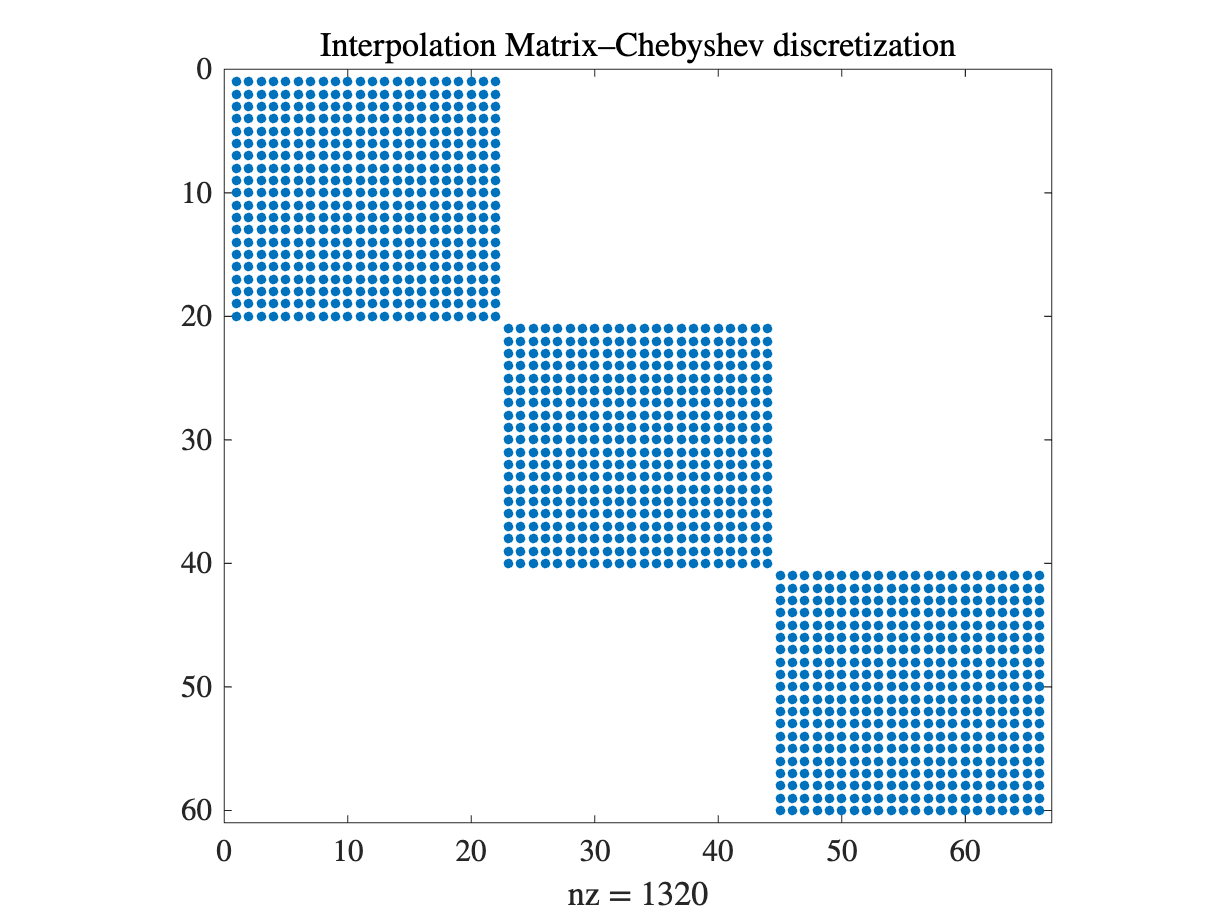

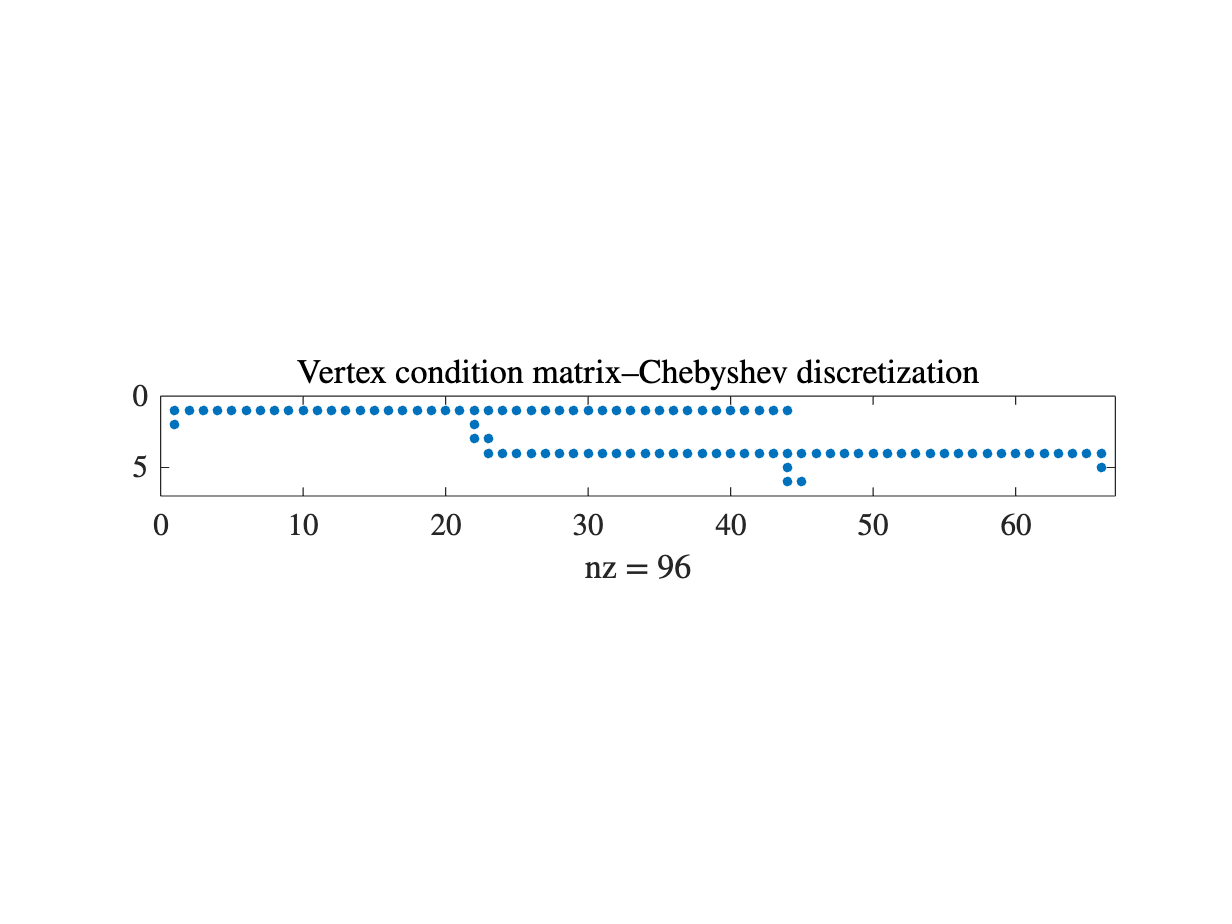

Phi = quantumGraphFromTemplate('dumbbell','Discretization','Chebyshev');
Phi.spy

## Setting up and solving problems on quantum Graphs

### A Schrodinger-Poisson problem

Set up a quantum graph in the form of a dumbbell plus one extra unbounded edge

Solve the vertex-value problem 


$$\triangle u - V(x)\, u= f \\
\sum w u'(\mathtt{v_1})+ u(\mathtt{v_1}) = 6 \\
\sum w u'(\mathtt{v_2})+ u(\mathtt{v_2}) = 3\\
u(\mathtt{v_3}) = \sech2
$$


where 

- The potential is $V(x) = \{ 2 \cos{2x},0,0,0,0\}$

- The functions on the right-hand-sides are $f = \left\{
-\sin{3x},
2\cos{2x},
-4,
-\sin{x},
\sech{x}-2 \sech^3{x}
\right\}$on the four edges.

- the edges have lengths $\left\{
\pi, 2\pi,1, 2\pi, 2
\right\}$.

- The exact solutions on the edges are $\left\{
\sin{x},
\sin^2{x},
3x-2x^2,
1+\sin{x},
\sech{x}
\right\}$.

#### Quantum graph definition

s=[1 1 1 2 2];
t=[1 1 2 2 3];
L=[pi 2*pi 1 2*pi 2];
robinCoeff=[1 1 nan];
weight = [1 1 2 1 1];

#### The exact solution

u1=@(x)sin(x);
u2=@(x)sin(x).^2;
u3=@(x)(3*x-2*x.^2);
u4=@(x)(1+sin(x));
u5=@(x)sech(x);

#### The right hand sides

Edges and nodes

f1=@(x)-sin(3*x);
f2=@(x)2*cos(2*x);
f3=-4;
f4=@(x)-sin(x);
f5=@(x)sech(x).*(1-2*sech(x).^2);
nodeData = [8;3;sech(2)];

#### The potential

potentialV = {@(x)(2*cos(2*x)),0,0,0,0};

#### Solve the system 

Define the quantum graph. Use the default value of about 20 discretization points per unit length.

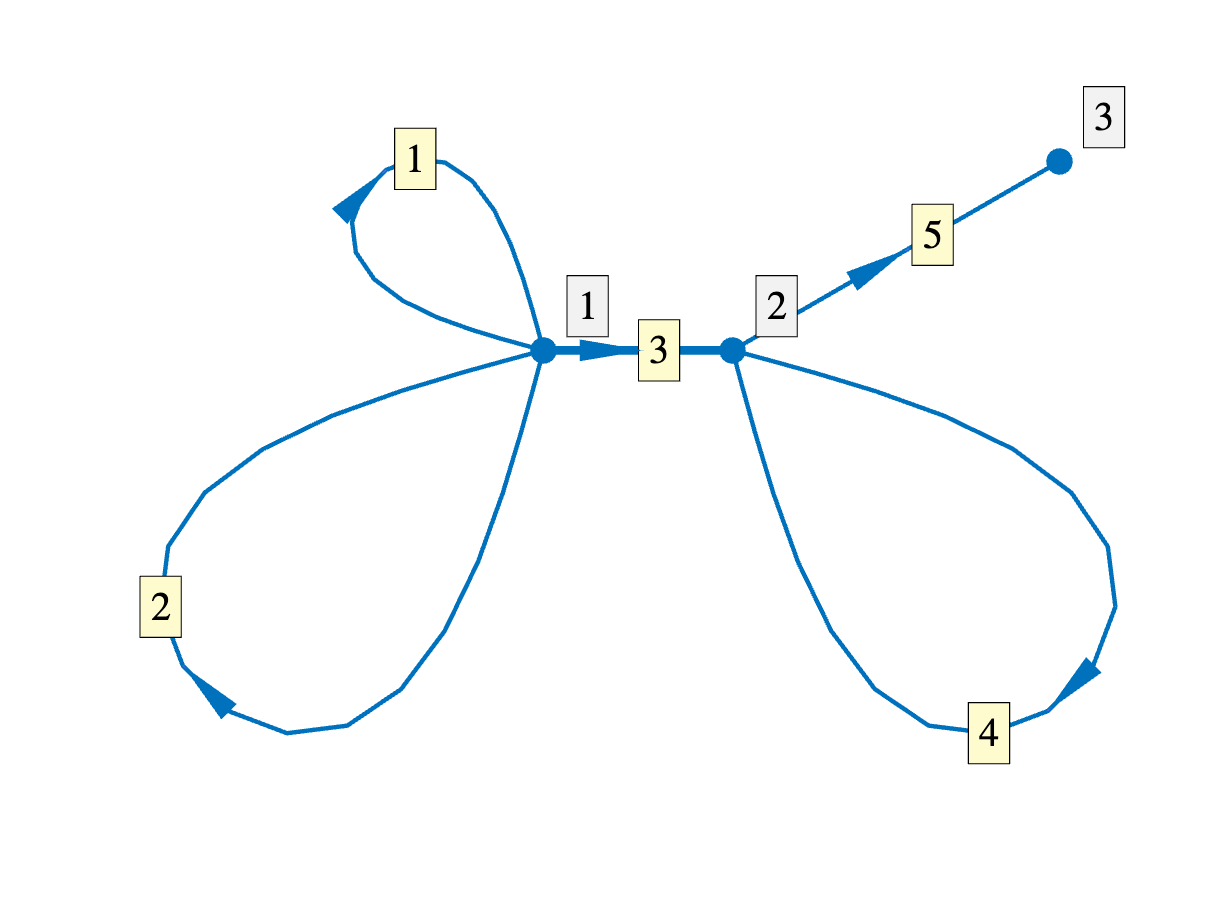

Phi=quantumGraph(s,t,L,'RobinCoeff',robinCoeff,'Weight',weight,'Discretization','Chebyshev');
Phi.addPlotCoords(@poissonExamplePlotCoords);
Phi.addPotential(potentialV);
Phi.plot('layout');

Set up the exact solution on the edges

exactSolution = Phi.applyFunctionsToAllEdges({u1,u2,u3,u4,u5});

Set up the nonhomogeneous data on the edges

edgeData = Phi.applyFunctionsToAllEdges({f1,f2,f3,f4,f5});

Solve and compute errors

numericalSolution = Phi.solvePoisson('edgeData',edgeData,'nodeData',nodeData);
numericalError= Phi.norm(exactSolution-numericalSolution,inf);
fprintf('The maximum error is %0.4d.\n',numericalError)

The maximum error is 1.0446e-10.


Plot the solution

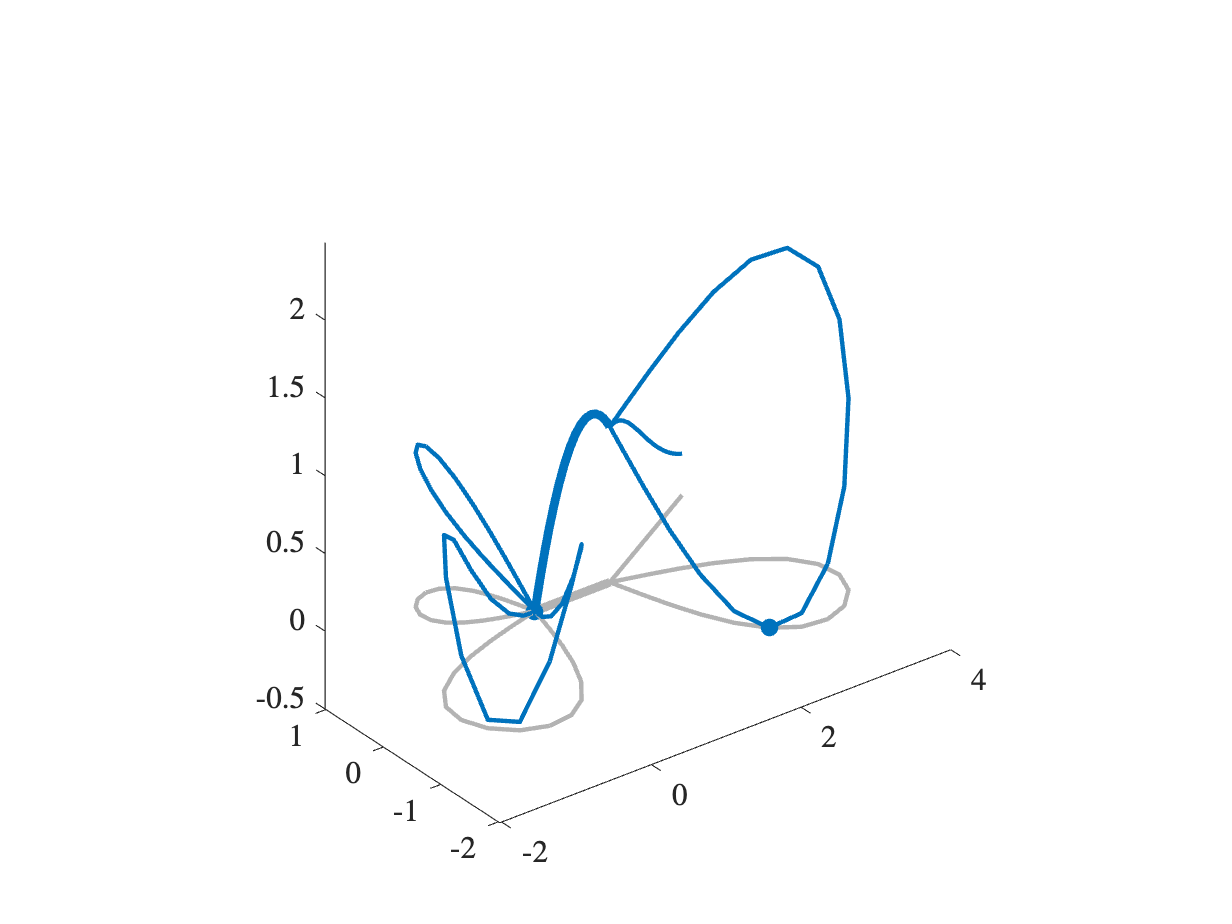

Phi.plot(numericalSolution)

### An eigenproblem

We compute the four eigenvalues closest to zero for the dumbbell quantum graph.

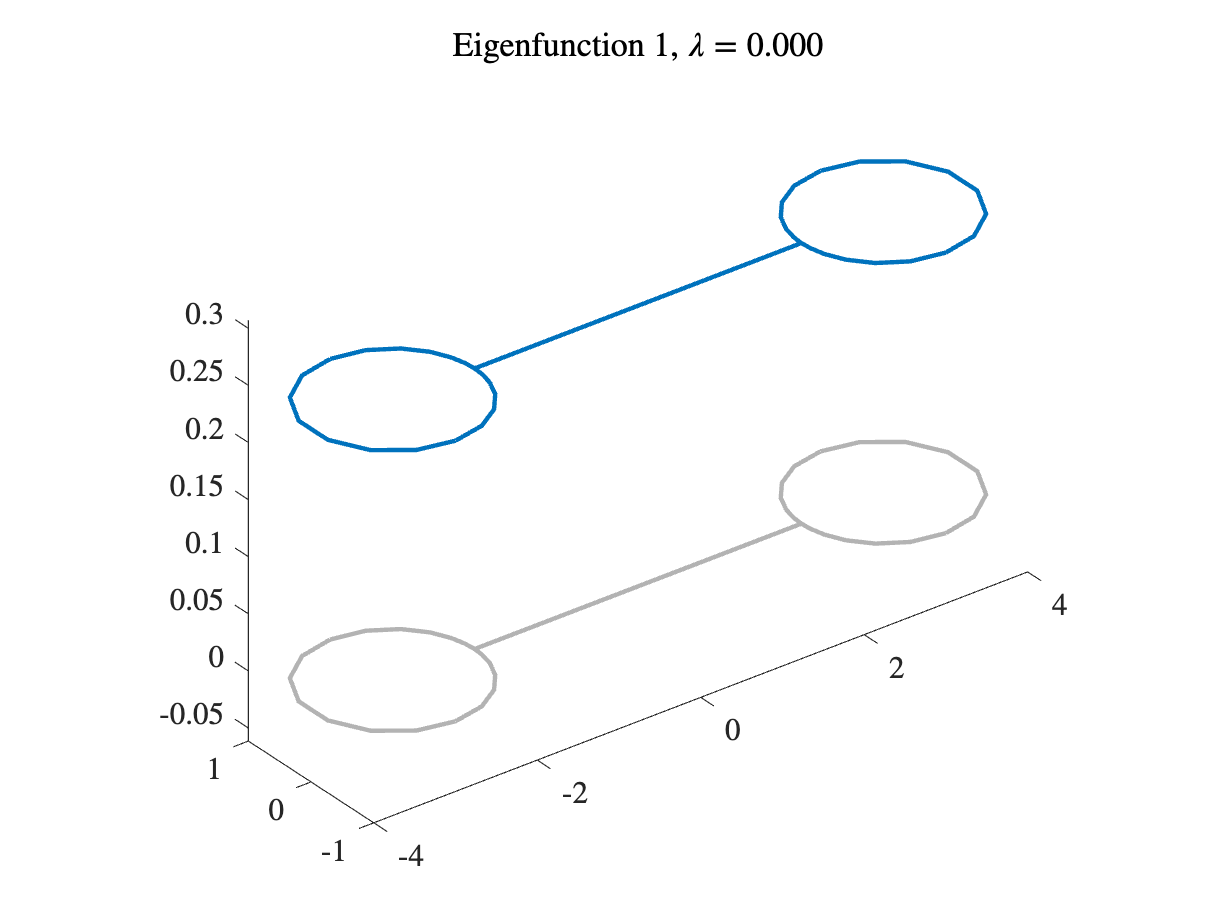

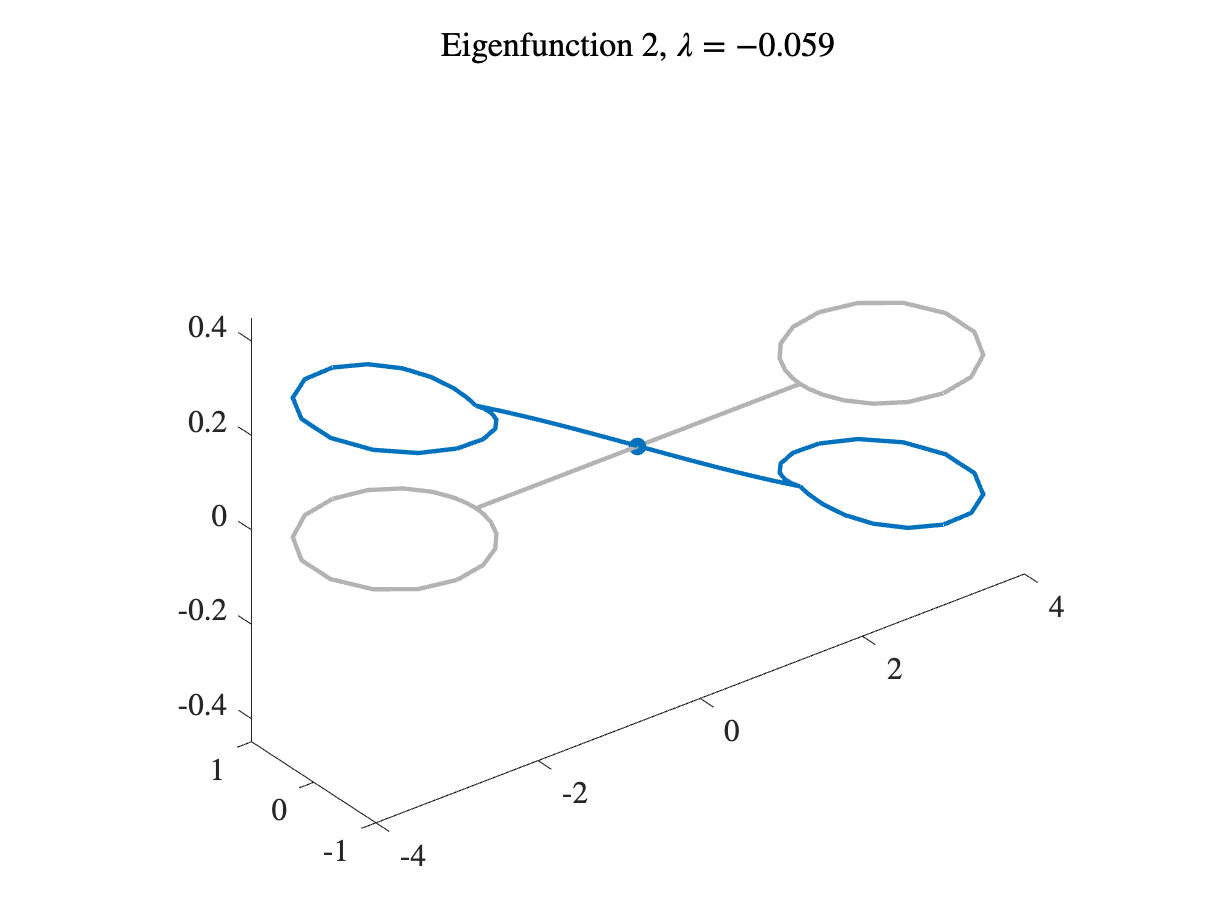

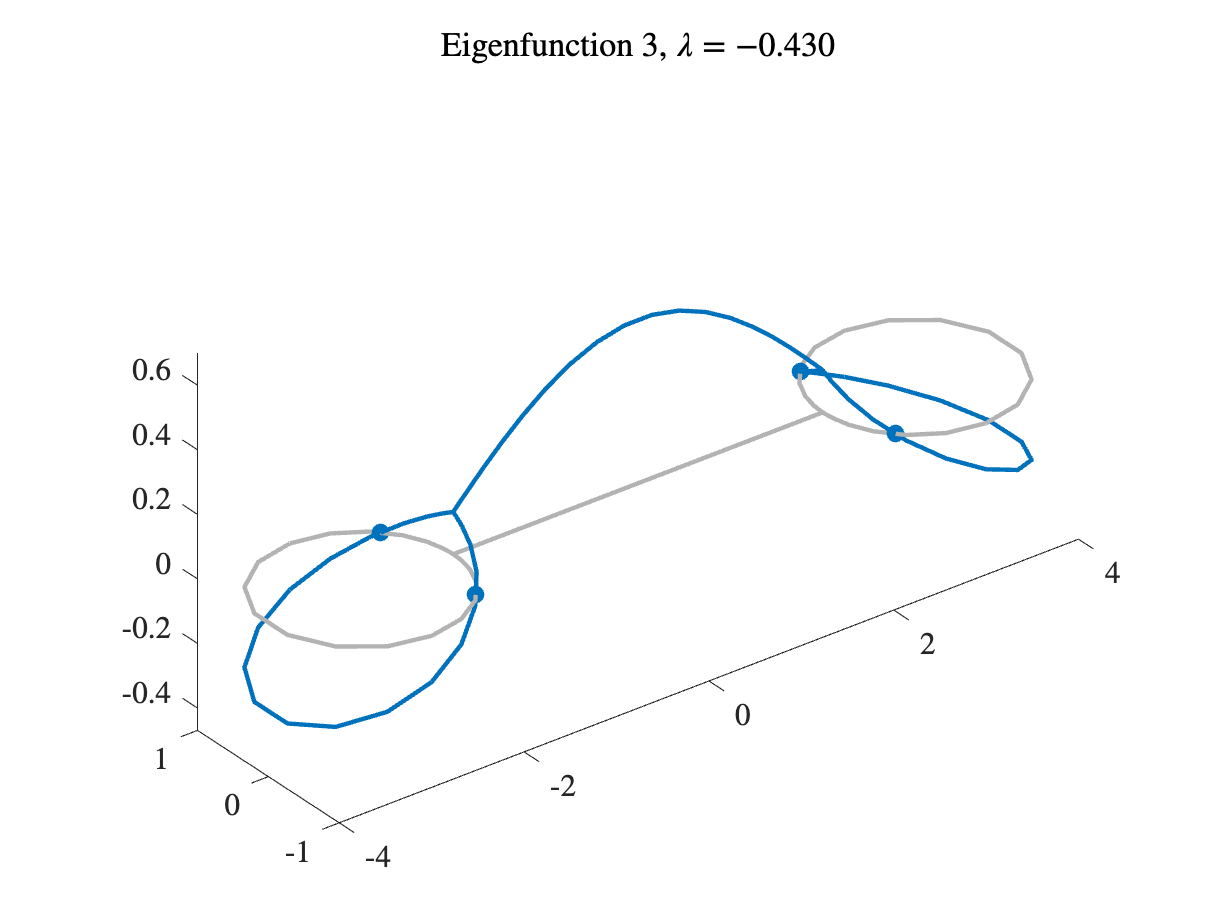

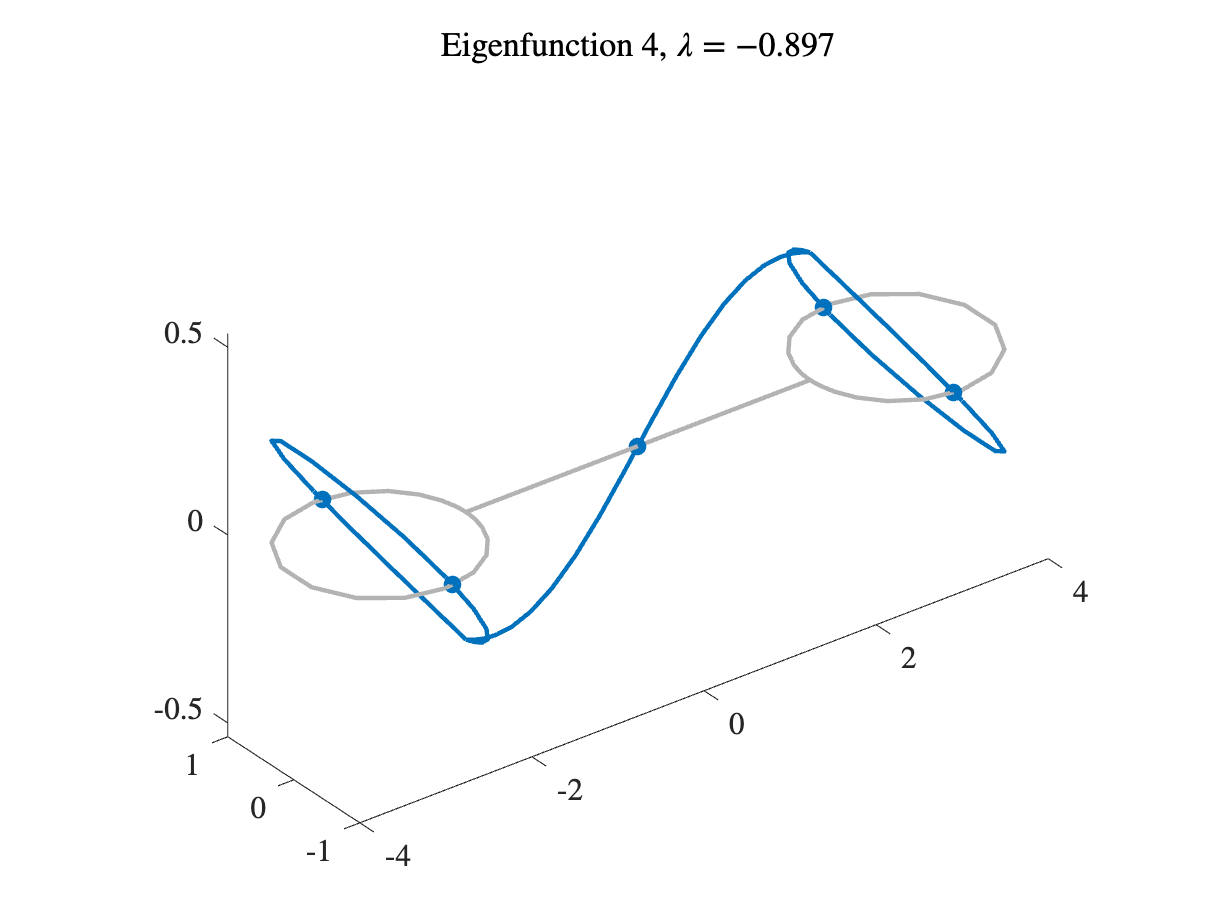

Phi=quantumGraphFromTemplate('dumbbell','Discretization','Chebyshev');
[V,lambda]=Phi.eigs(4);
for k=1:4
    figure
    Phi.plot(V(:,k))
    title(sprintf('Eigenfunction %i, $\\lambda = %0.3f$', k, lambda(k)));
end

#### The secular determinant

The eigenvalues of quantum graph are given by $\lambda=-k^2$ where $k$ is a root of a function called the *secular determinant*. This function is defined by noting that on each edge, the eigenfunction must be a linear combination of $\sin{kx$ and $\cos{kx}$, and attempting to enforce the vertex conditions. The following code constructs the secular determinant as a symbolic expression $f(k)$. 

f=secularDet(Phi)

$$f = -\frac{\left(\cos\left(2\,\pi \,x\right)-1\right)\,\left(4\,\cos\left(4\,x\right)\,\sin\left(2\,\pi \,x\right)-3\,\sin\left(4\,x\right)+5\,\sin\left(4\,x\right)\,\cos\left(2\,\pi \,x\right)\right)}{4}$$

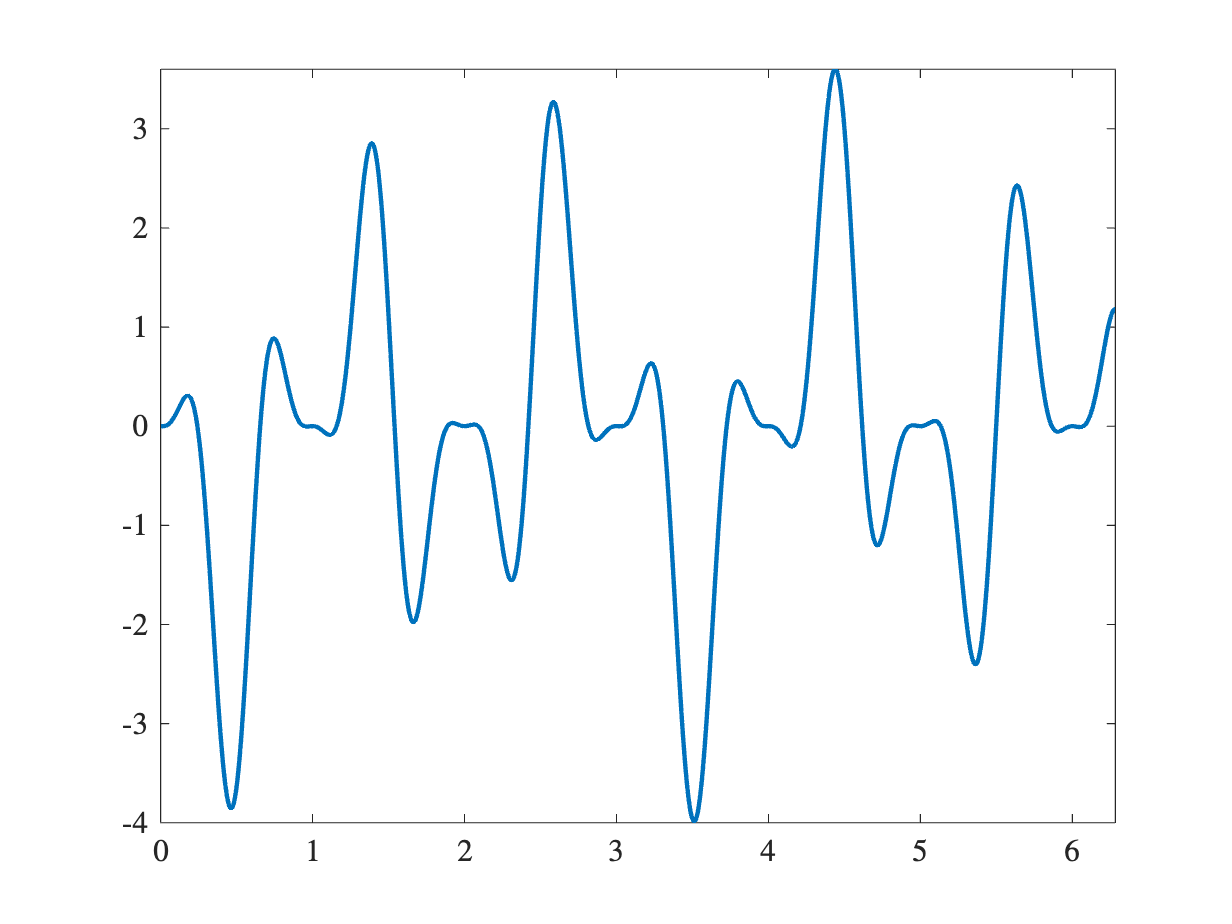

fplot(f,[0 2*pi])

k=linspace(0,1);
ff=matlabFunction(f);
fk=ff(k);

The smallest root is just $k=0$. Find the next three and see that they agree with the eigenvalues to all digits shown

guesses=find(fk(1:end-1).*fk(2:end)<0);
fprintf('Numerical  Analytical')

Numerical  Analytical

for i=1:3
    kstar=fzero(ff,k(guesses(i)));
    fprintf('%2.5f    %2.5f\n',lambda(i+1),-kstar^2)
end

-0.05857    -0.05857
-0.42970    -0.42970
-0.89706    -0.89706


### Drawing a bifurcation diagram

This code draws the bifurcation diagram from Figure 3.3 of Goodman, R. H. [NLS bifurcations on the bowtie combinatorial graph and the dumbbell metric graph.](http://doi.org/10.3934/dcds.2019093) **Discrete & Continuous Dynamical Systems - A,** 39(4), 2203–2232 (2019) plus some extra branches to show how the code works.

#### Construct the quantum graph and find the first few eigenfunctions

tag='dumbbell';
L = [2*pi 4 2*pi];
nxvec=6;
Phi=quantumGraphFromTemplate(tag,'LVec',L,'nX',nxvec,'discretization','Uniform');
dataDir = makeContinuationDirectory(Phi,tag);

Created directory data/dumbbell/184.


#### Compute and save some eigenfunctions

nToPlot=4;
nDoubles=1;
saveEigenfunctions(Phi,tag,dataDir,nToPlot,nDoubles);

#### Define the cubic nonlinearity and save it to the data directory. 

This must be a symbolic function of a single variable `z`.

syms z
f = 2*z^3;
fcns = saveNLSFunctionsGraph(dataDir,Phi,f);

#### Compute branches that are continuation of the three least oscillatory eigenfunctions

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

options=continuerSet([],'LambdaThresh',-3,'NThresh',9,'plotFlag',false,'minNormDelta',1e-3);
branch1=continueFromEig(dataDir,1,options);

N threshold 9.0 crossed.
Branch number 1.
Data saved to directory data/dumbbell/184/branch001.
Branching Bifurcation at solution number 6.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 12.
Branching Bifurcation at solution number 14.


branch2=continueFromEig(dataDir,2,options);

Lambda threshold -3.0 crossed.
Branch number 2.
Data saved to directory data/dumbbell/184/branch002.
No branching bifurcations found.


branch3=continueFromEig(dataDir,3,options);

N threshold 9.0 crossed.
Branch number 3.
Data saved to directory data/dumbbell/184/branch003.
No branching bifurcations found.


#### Compute some branches that bifurcate from this first branch

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a symmetry-breaking bfirucation, we only need to continue in one direction, the branch stored in `branch1` at bifurcation location 1 

location=1;
direction=1;
branch4=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold -3.0 crossed.
Branch number 4.
Data saved to directory data/dumbbell/184/branch004.
No branching bifurcations found.


- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a transcritical bfirucation, we need to continue in both directions, the branch stored in `branch1` at bifurcation location 2

location=2;
direction=1;
branch5=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold -3.0 crossed.
Branch number 5.
Data saved to directory data/dumbbell/184/branch005.
Branching Bifurcation at solution number 21.


location=2;
direction=-1;
branch6=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold -3.0 crossed.
Branch number 6.
Data saved to directory data/dumbbell/184/branch006.
No branching bifurcations found.


#### Compute a branch that bifurcates from the third branch

Continues from the branch stored in `branch5` from the bifurcation point 1

location=1;
direction=1;
branch7=continueFromBranchPoint(dataDir,branch5,location,direction,options);

Lambda threshold -3.0 crossed.
Branch number 7.
Data saved to directory data/dumbbell/184/branch007.
No branching bifurcations found.


#### Compute a large-amplitude solution, save it to a file, and compute its continuation

This seeds a standing wave with large frequency, localized and with positive amplitudes on edges 1 and 2.

Lambda0=-4;
edges=[1 2];
signs=[1 1];
filenumber=saveHighFrequencyStandingWave(dataDir,Lambda0,edges,signs);

File saved to data/dumbbell/184/savedFunction.001.
File number is 1. 


options=continuerSet(options,'LambdaThresh',-4.1,'NThresh',9);
direction=-1;
branch8=continueFromSaved(dataDir,filenumber,direction,options);

N threshold 9.0 crossed.
Branch number 8.
Data saved to directory data/dumbbell/184/branch008.
No branching bifurcations found.


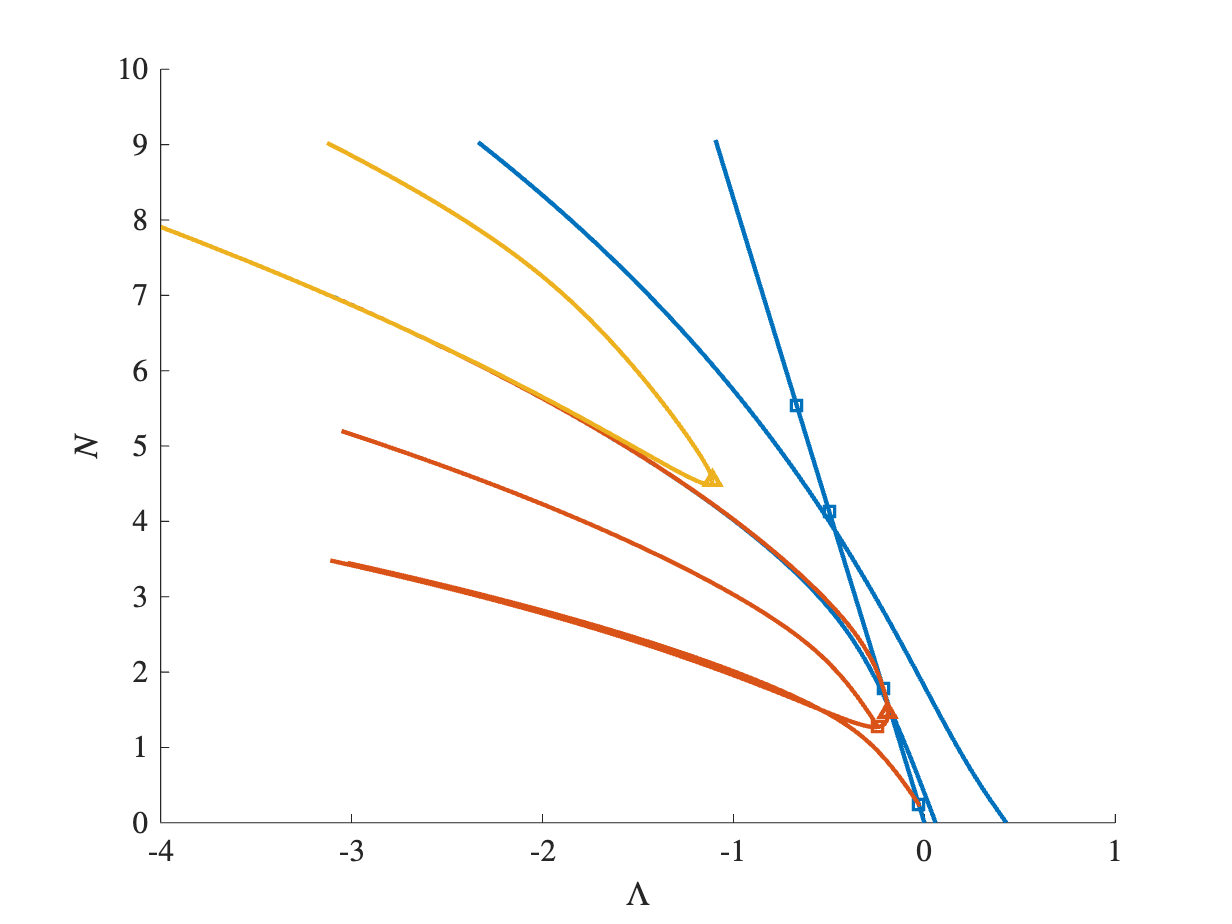

bifurcationDiagram(dataDir)

#### Plot some solutions

The fifteenth computed solution on branch 4:

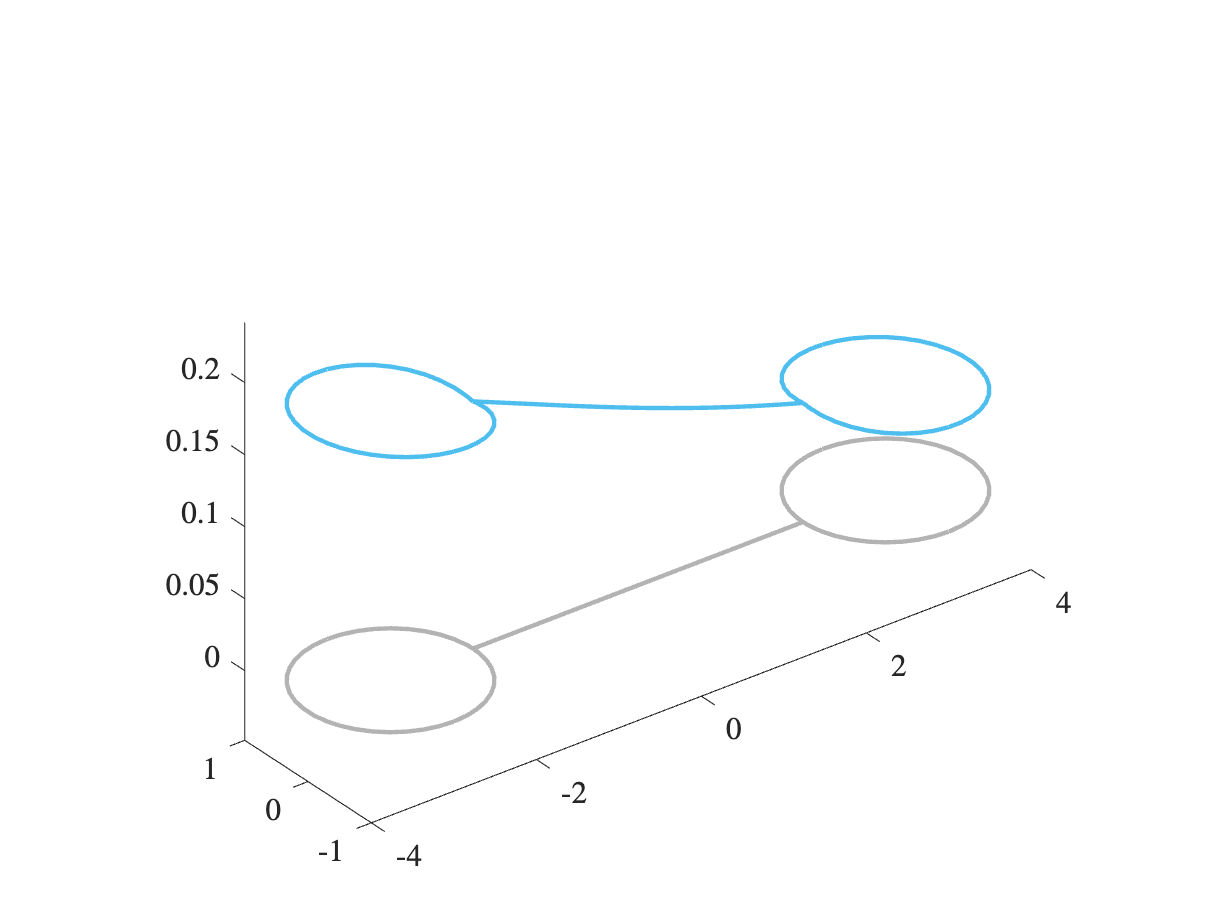

plotSolution(dataDir,branch4,15)

The last computed solution on branch 8:

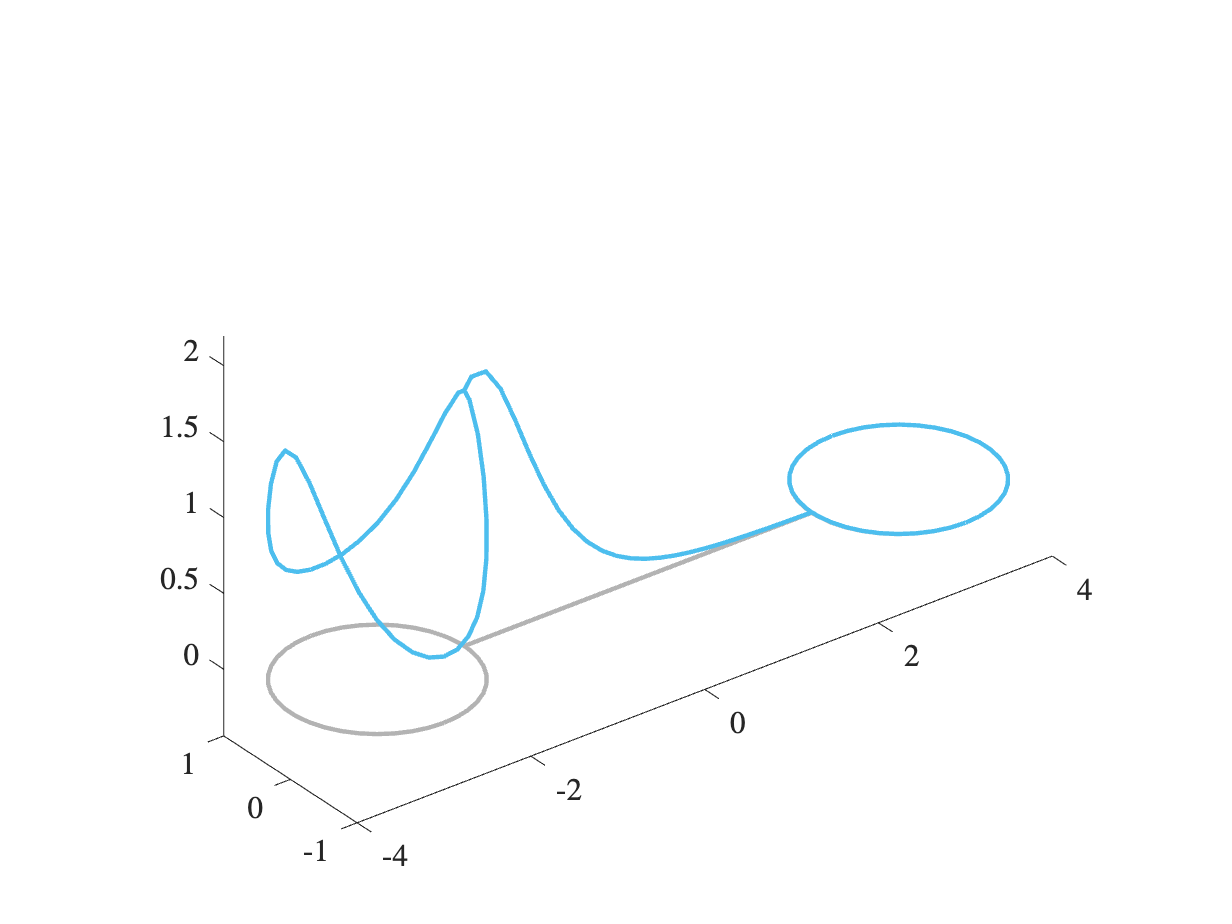

plotSolution(dataDir,branch8,'last')

### Heat flow on a dumbbell graph

In this example, we adapt a standard time-stepper, the Crank-Nicholson method to the block matrix formulation. We solve the heat equation $u_t = \triangle u$ on a dumbbell graph.

The standard Crank-Nicholson method with time step $h$ is:

$\left(I - \frac{h}{2}\triangle\right)u_{k+1} = 
 \left(I +\frac{h}{2}\triangle\right) u_k$.

We must modify that to ensure that $u_{k+1}$ satisfies the discrete vertex conditions. In the notation of the paper we let


$$\mathbf{L}_-  = \binom{\mathbf{P}_{\rm int} - \frac{h}{2} \mathbf{L}_{\rm int}} {\mathbf{M}_{\rm VC}} 
 \text{ and }
\mathbf{L}_+ =  \binom{\mathbf{P}_{\rm int} + \frac{h}{2} \mathbf{L}_{\rm int}} {\mathbf{0}}$$


and then iterate $\mathbf{L}_- u_{k+1} = \mathbf{L}_+ u_k$. The matrices are defined blockwise, with the upper blocks represent the differential equation on the edges' interiors and the bottom blocks enforce the vertex conditions.

#### Set up the graph and the initial condition

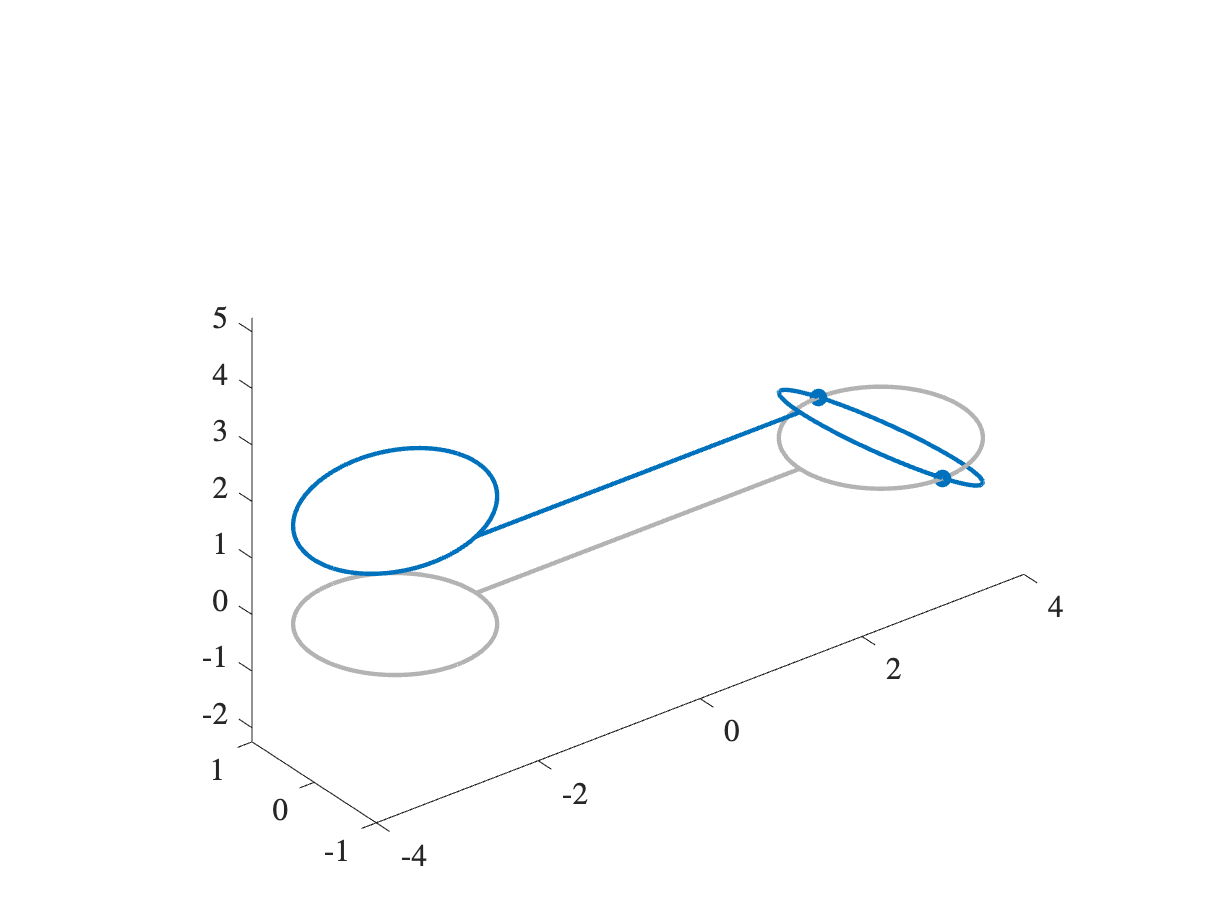

Phi=quantumGraphFromTemplate('dumbbell');
f0=@(x)(2-2*cos(x-pi/3));
f1=1;
f2=@(x)cos(x);
y=Phi.applyFunctionsToAllEdges({f0,f1,f2});
totalHeatInitial = Phi.integral(y);
figure;Phi.plot(y);

#### Set up the time stepping

h=0.01;
tFinal=10;
nStep=tFinal/h;

#### Set up the evolution matrices

Lint=Phi.wideLaplacianMatrix;
Pint=Phi.interpolationMatrix;
Lplus=Phi.extendWithZeros(Pint+h/2*Lint);
Lminus=Phi.extendWithVC(Pint-h/2*Lint);

#### Evolve  the solution

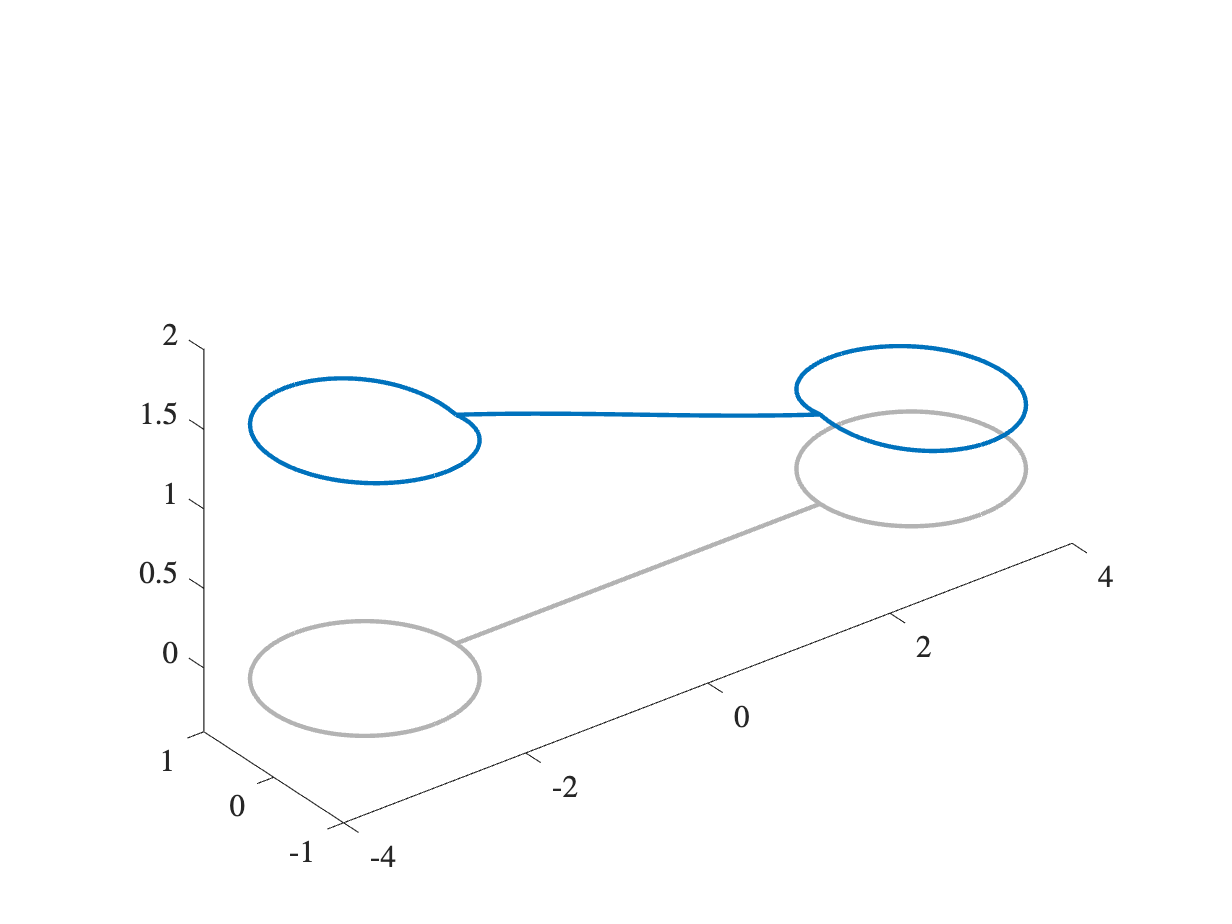

keepCount=1;
for k=1:nStep
    y = Lplus*y;
    y = Lminus\y;
end
totalHeatFinal = Phi.integral(y);
figure;Phi.plot(y);

#### Show that the total heat is conserved to many digits

fprintf('Change in heat is %0.2e.\n',totalHeatFinal-totalHeatInitial);

Change in heat is -1.58e-12.


## KPP evolution on a honeycomb

Evolves a solution to the KPP equation $u_t = \mu \triangle u + u(1-u)$ on a honeycomb graph. Here we evolve the approximate solution using the QGLAB function

Phi = hexOfHexes("cellsPerSide",4,"nx",32);

## Define and plot the initial conditions 

We choose an initial condition which is a Gaussian based on the physical coordinates of the points on the graph. This graph has 132 edges and we center the initial condition on the center of edge $\mathtt{e}_{53}$.

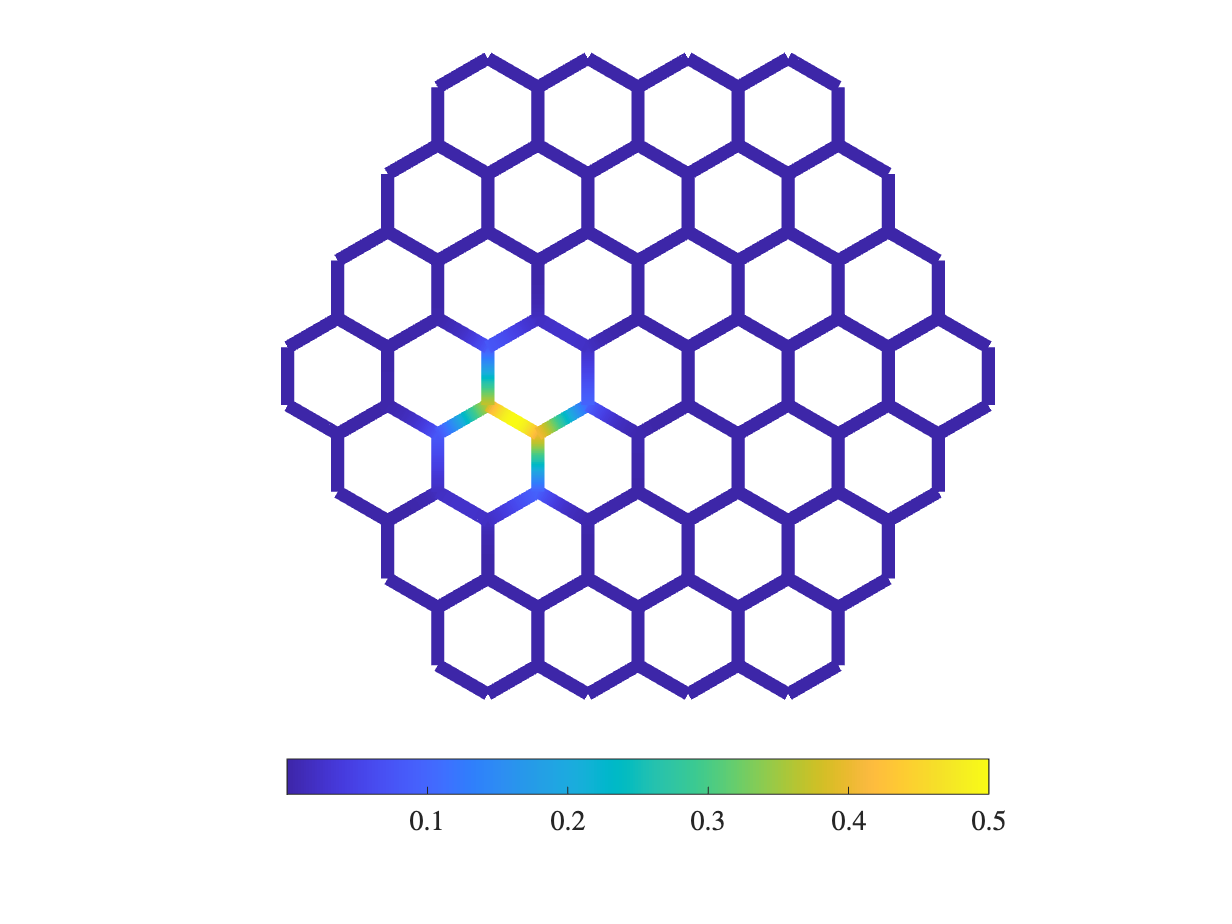

centerEdge=53;
spot=round(Phi.nx(centerEdge)/2);
X1=Phi.Edges.x1{centerEdge}(spot);
X2=Phi.Edges.x2{centerEdge}(spot);
f0 = @(x1,x2)exp(-(x1-X1).^2-(x2-X2).^2)/2;
u0 = Phi.applyGraphicalFunction(f0);
Phi.pcolor(u0)

## Function Definition and Time evolution


$$f(t,u) = \mu \triangle u + F(t,u)$$


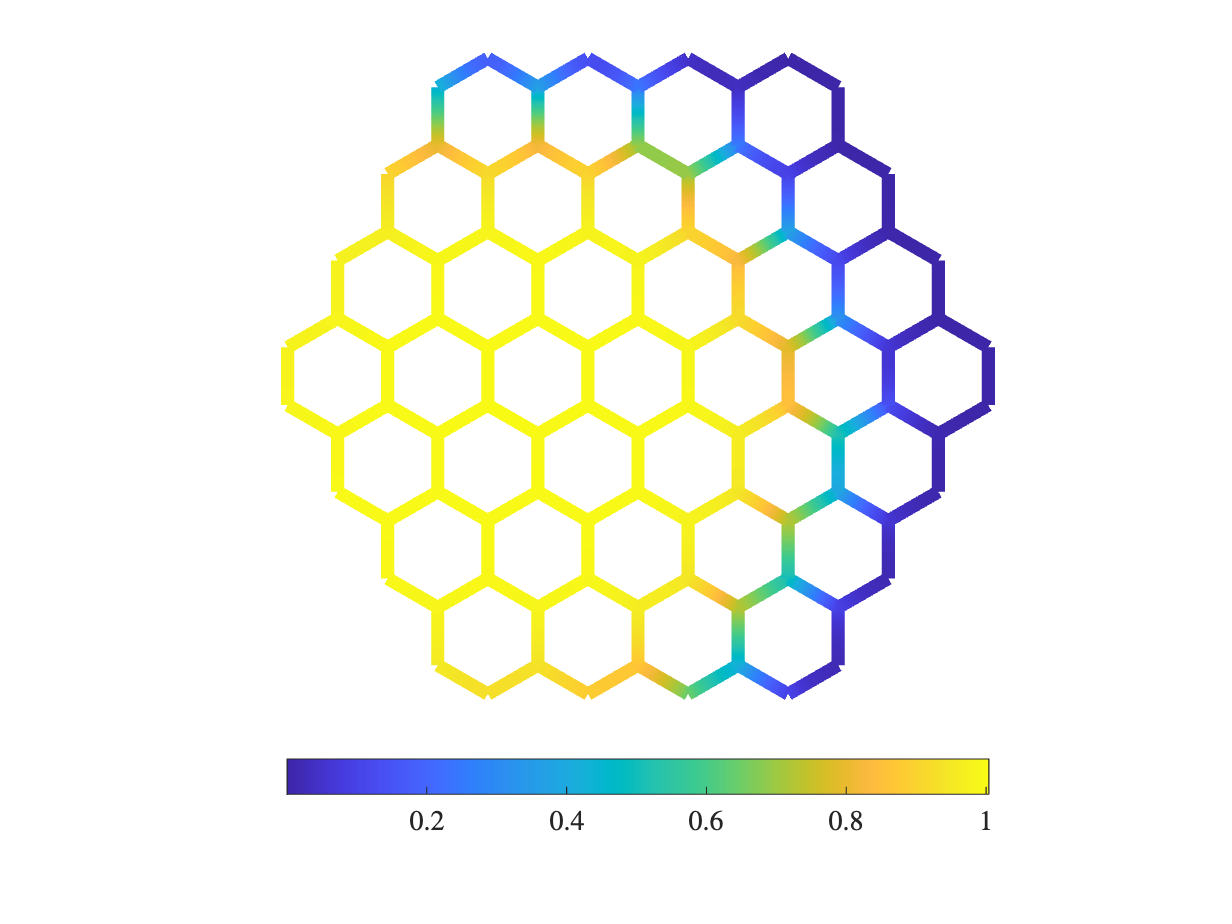

mu = 0.1;
F =@(z) z.*(1-z);
tFinal = 12;
dt = 0.1;
[t,u] = Phi.qgdeSDIRK443(mu,F,tFinal,u0,dt,'nSkip',10);
Phi.pcolor(u(:,end))